clear all
load features_panneaux.mat



tab_features = [struct_features_pan.ref30 struct_features_pan.ref50 struct_features_pan.ref70 struct_features_pan.ref90 struct_features_pan.ref110];
n = size(tab_features,2);

feat_commun_par_ref = [0 0 0 0 0];

feat_ref = [struct_features_pan.ref30{2}.Count struct_features_pan.ref50{2}.Count struct_features_pan.ref70{2}.Count struct_features_pan.ref90{2}.Count struct_features_pan.ref110{2}.Count];
probas_ref = feat_ref/sum(feat_ref);
imagetest = imread("route50.jpg"); % image préalablement filtrée
imagetest = rgb2gray(imagetest);


## test de caractéristiques

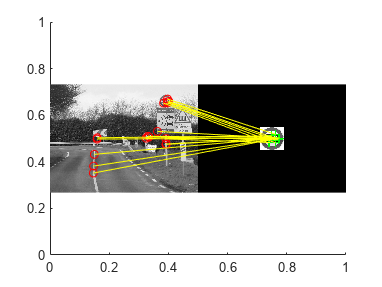

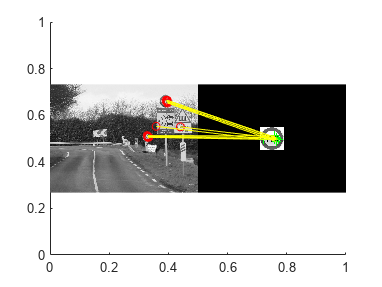

% on récupère les features de l'image filtrée
points = detectSURFFeatures(imagetest);
[features, valid_points] = extractFeatures(imagetest,points,'Upright',true);

hold off;

ax = axes;

%on compare a chaque ref
for i = 1:3:n-2
    %on extrait les features
    features_ref = tab_features{i};
    valid_points_ref = tab_features{i+1};
    image_col_ref = tab_features{i+2};
    %%%%%%%%%%%%%%%%%%%%%%%%%%%

    % on compare les features test avec les features ref
    indexPairs = matchFeatures(features,features_ref,"MaxRatio",0.95);

    matchedPoints1 = valid_points(indexPairs(:,1),:);
    matchedPoints2 = valid_points_ref(indexPairs(:,2),:);

    feat_commun_par_ref((i-1)/3+1) = size(matchedPoints2,1); %on recup nb features par ref

    if i == 1
        figure(1) %on affiche les resultats
        showMatchedFeatures(imagetest,rgb2gray(image_col_ref),matchedPoints1,matchedPoints2,'montage');
    elseif i == 4
        figure(4) %on affiche les resultats
        showMatchedFeatures(imagetest,rgb2gray(image_col_ref),matchedPoints1,matchedPoints2,'montage');
    elseif i == 7
        figure(7) %on affiche les resultats
        showMatchedFeatures(imagetest,rgb2gray(image_col_ref),matchedPoints1,matchedPoints2,'montage');
    elseif i == 10
        figure(10) %on affiche les resultats
        showMatchedFeatures(imagetest,rgb2gray(image_col_ref),matchedPoints1,matchedPoints2,'montage');
    elseif i == 13
        figure(13) %on affiche les resultats
        showMatchedFeatures(imagetest,rgb2gray(image_col_ref),matchedPoints1,matchedPoints2,'montage');
    end
    
    %title(ax, 'point matches');
    %legend(ax,'Matched points 1','Matched points 2');
end


nb_feat_total = sum(feat_commun_par_ref);
probas_par_ref = feat_commun_par_ref/nb_feat_total;
sum(probas_par_ref) == 1;